# Thermal Calculator

Main Document [here](https://docs.google.com/document/d/1MgEfN8uAGja6VMx7kqAkoUOlrUCEuHOKKBFwb_MEE9E/edit?usp=sharing)

Thermal Stage Doc [here](https://docs.google.com/document/d/1LFotCKugJQmg7X97VCYzZdj7jm384hpMmckm8d77kWU/edit)

## Physical Constants

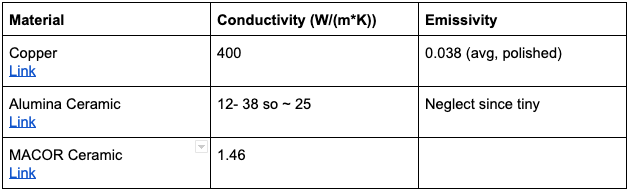

For zirconia spacers (k = 2.2 W/(m*K)) for M3 screws from [here](https://www.ortechceramics.com/products/uncategorized/ceramic-washers/)

- Inner diameter 3.50 – 3.68

- Outer diameter 9.64 – 10.0

- Thickness 0.80 – 1.20

Glass spacers from pyrex might be better

cd 'C:\Users\johns\Documents\Github\QEM-MATLAB'
SetVariables;
load ImpVariables.mat;
mat2Cond = 1; % for glass
mat1Emis = 0.038; % for polished copper

## Radiation Term


$$P_{rad} = e\sigma A(T_{hot}^4 - T_{room}^4)$$


% Object Dimensions
length = 20*c.milli;
width = 7*c.milli;
thick = 3*c.milli;
surfaceArea = 2*length*width+ 2*length*thick + 2*thick*width;
zeroC = 273.15;
T_hot = 250 + zeroC;
T_cold = 20 + zeroC;
P_rad = mat1Emis*c.stephBoltz*surfaceArea*(T_hot^4-T_cold^4)

P_rad = 0.0643

## Conduction Term

Assuming cylindrical spacers of height and internal/external radiuses given, with perfect thermal contact

height = 10*c.milli;
inRad = 3.5*c.milli;
outRad = 4.5*c.milli;

condArea = pi*outRad^2 - pi*inRad^2;
P_cond = mat2Cond*condArea*(T_hot-T_cold)/height

P_cond = 0.5781

## Radiation Balance Calc

% Assuming emissivity equivalent... and only laser heated area radiates
Pabs = [0.1 0.3 1 3 10 30 100 300 1000]*c.milli; %input power (W)
r = 1; %ratio of emissivities
d = 1*c.milli; %diameter (m) of spot (tophat)
Tc = 273.15; %temp of surrounding (K)

Ain = pi*d^2/4; %illuminated area

T = (Pabs*r/(Ain*c.stephBoltz)+(Tc+25)^4).^(1/4)-Tc % Temperature in steady state (degC)

T = 	1.0e+03 *

    0.0442    0.0747    0.1443    0.2506    0.4212    0.6354    0.9521    1.3384    1.9039


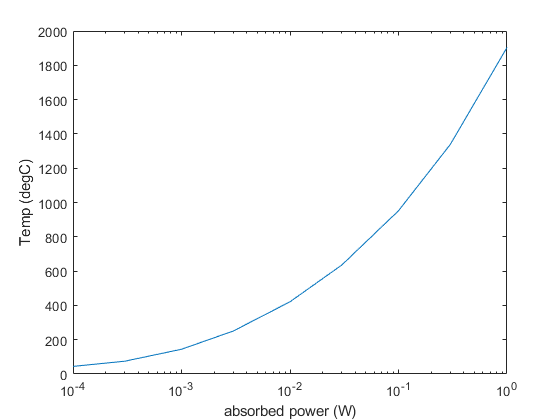

semilogx(Pabs, T); xlabel('absorbed power (W)'); ylabel('Temp (degC)')

## Graphene Reflection/Deflection Coefficients

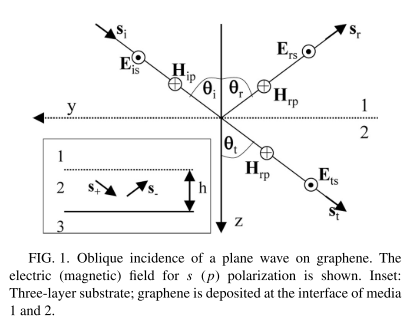

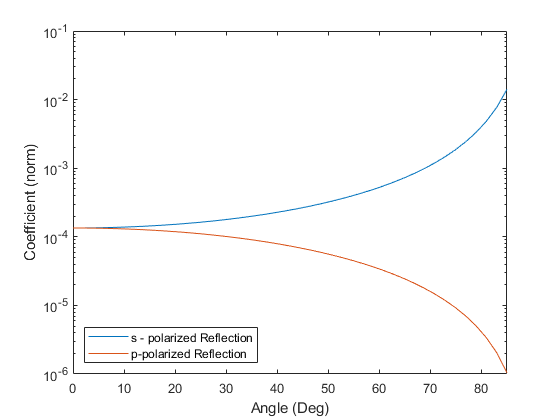

% Vacuum suspended graphene from Merano, M. (2016). Fresnel coefficients of a two-dimensional atomic crystal. Physical Review A, 93(1), 1–5. https://doi.org/10.1103/PhysRevA.93.013832
lambda = 1000*c.nano; % laser wavelength (nm)
xi = 8e-10; % electrical susceptibility (m) +-3e-10
sigma = 6.08e-5; % conductivity (1/ohm), set by constant(e^2)/(4*hbar), +-2e-5
eta = c.Zo_SI; %impedance of vacuum (ohm)
k = 2*pi/lambda;
maxAngle = 85;
thetaDeg = linspace(0, maxAngle, maxAngle/2+1) ; %Degrees
theta = thetaDeg*pi/180 ; % Angle (radians)

sum_term = (i*k*xi + sigma*eta);
r_s = -sum_term./(sum_term+2*cos(theta));
r_p = sum_term*cos(theta)./(sum_term*cos(theta)+2);
t_s = r_s + 1;
t_p = 1 - r_p;

R_s = abs(r_s).^2;
R_p = abs(r_p).^2;
T_s = abs(t_s).^2;
T_p = abs(t_p).^2;

semilogy(thetaDeg, [R_s; R_p])
xlabel('Angle (Deg)')
xlim([0 maxAngle])
ylabel('Coefficient (norm)')
legend('s - polarized Reflection', 'p-polarized Reflection', 'location', 'southwest')


L_s = 1 - R_s-T_s

L_s =     0.0224    0.0224    0.0224    0.0225    0.0226    0.0227    0.0229    0.0231    0.0233    0.0235    0.0238    0.0241    0.0245    0.0249    0.0254    0.0259    0.0264    0.0270    0.0277    0.0284    0.0292    0.0301    0.0311    0.0322    0.0334    0.0348    0.0363    0.0381    0.0400    0.0422    0.0447    0.0476    0.0509    0.0549    0.0595    0.0651    0.0720    0.0806    0.0916    0.1062    0.1265    0.1566    0.2052


L_p = 1 - R_p-T_p

L_p =     0.0224    0.0224    0.0223    0.0223    0.0222    0.0220    0.0219    0.0217    0.0215    0.0213    0.0210    0.0208    0.0204    0.0201    0.0198    0.0194    0.0190    0.0185    0.0181    0.0176    0.0171    0.0166    0.0161    0.0155    0.0149    0.0143    0.0137    0.0131    0.0124    0.0118    0.0111    0.0104    0.0097    0.0089    0.0082    0.0075    0.0067    0.0059    0.0052    0.0044    0.0036    0.0028    0.0020


L_unpolarized = (L_s+L_p)/2

L_unpolarized =     0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0224    0.0225    0.0225    0.0225    0.0226    0.0226    0.0227    0.0228    0.0229    0.0230    0.0232    0.0234    0.0236    0.0239    0.0242    0.0246    0.0250    0.0256    0.0262    0.0270    0.0279    0.0290    0.0303    0.0319    0.0339    0.0363    0.0394    0.0433    0.0484    0.0553    0.0651    0.0797    0.1036


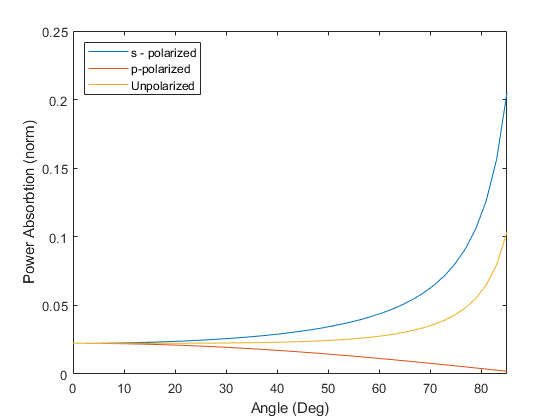


plot(thetaDeg, [L_s; L_p; L_unpolarized])
xlabel('Angle (Deg)')
ylabel('Power Absorbtion (norm)')
legend('s - polarized', 'p-polarized', 'Unpolarized', 'location', 'northwest')
xlim([0 maxAngle])

## Ellipse Area Normalization

area = pi*